folder = "D:\Whale Data\Raw Audio Data\CaseyIslands2017";
dsname = "CaseyIslands2017";

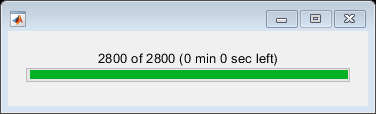

det = Detector(dsname, 0.1);
det.detections();

detectors = load(folder + "\\detectors\\detectors.mat").D;
segmm = [detectors.segmmwhite];
anns = {detectors.annotations};
info = [detectors.info];
clear detectors

conv = arrayfun(@(d) d.converged, segmm);
segmmconv = segmm(conv);
annsconv = anns(conv);
infoconv = info(conv);


load(folder + "\\spectrograms\\filterbank.mat");
fsspec = fb.getSSamplingFreq()

fsspec = 2.0704

load(folder + "\\scattering\\filterbank.mat");
fsscat = fb.filterBanks(1).getSSamplingFreq()

fsscat = 0.3347

keepann = arrayfun(@(idx) size(anns{idx}, 1) > 0, 1:numel(anns));
annws = anns(keepann);
infows = info(keepann);
annwsall = arrayfun(@(idx) getScatCoeff(annws{idx}, infows(idx), folder, idx, fsscat, fsspec), 1:numel(annws), UniformOutput=false);

idx = 100

idx = 200

idx = 300

idx = 400

idx = 500

idx = 600

idx = 700

idx = 800

idx = 900

idx = 1000

idx = 1100

annwsall = vertcat(annwsall{:});


%baseline accuracy by only considering the annotated segments
annws = annwsall(annwsall.AnnotationSignificance < 1 & annwsall.AnnotationToNoiseRatioDB > -100, :);
counts = groupcounts(annws, "Annotation")

counts = 7×3 table
         Annotation         GroupCount    Percent
    ____________________    __________    _______

    "Bm_Ant-A"                 1739        51.45 
    "Bm_Ant-B"                  556        16.45 
    "Bm_Ant-Z"                  119       3.5207 
    "Bm_D"                      546       16.154 
    "Bp_20Hz"                    78       2.3077 
    "Bp_20Plus"                 214       6.3314 
    "Unidentified_calls"        128        3.787 


classes = counts{1:6, "Annotation"}

classes = 6×1 string array
    "Bm_Ant-A"
    "Bm_Ant-B"
    "Bm_Ant-Z"
    "Bm_D"
    "Bp_20Hz"
    "Bp_20Plus"


X = annws{any(annws.Annotation == classes', 2), "WS"};

y = annws{any(annws.Annotation == classes', 2), "Annotation"};
y(contains(y, "Bp")) = "Fin";
y(contains(y, "Fin")) = "Fin";
y(contains(y, "Bm")) = "Blue";
classes = ["Fin", "Blue"];
X = vertcat(X{:});
idxs = splitlabels(y, 0.3, "randomized")

idxs = 2×1 cell array
    { 976×1 double}
    {2276×1 double}


Xn = ((X-mean(X, 1))./std(X, 1));
Xtrain = Xn(idxs{1}, :);
ytrain = y(idxs{1}, :);
Xtest = Xn(idxs{2}, :);
ytest = y(idxs{2}, :);
cls = fitclinear(Xtrain, ytrain);
ypred = cls.predict(Xtest);
[c, order] = confusionmat(ytest, ypred)

c =         2032          40
          35         169


order = 2×1 string array
    "Blue"
    "Fin"


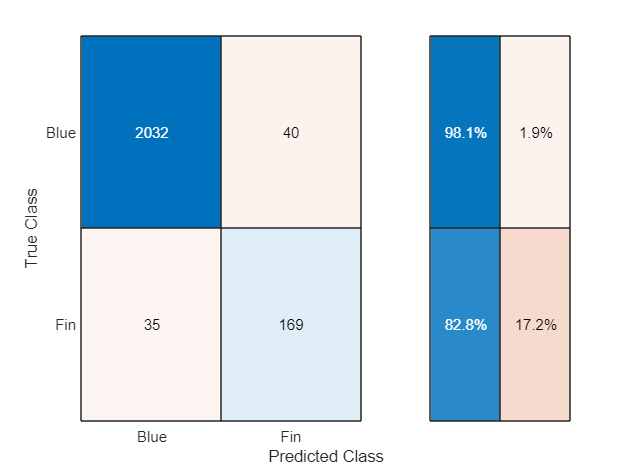

figure
confusionchart(c, order, "RowSummary","row-normalized")


% N = [4, 2];
% [~, sidx] = sort(order);
% csplit = cellfun(@(c)sum(c, "all"), mat2cell(c(sidx, sidx),N,N))
% figure
% confusionchart(csplit, ["Blue", "Fin"], "RowSummary","row-normalized")

colors = ones(numel(classes), 3);
colors(:, 1) = linspace(0, 0.3, numel(classes))

colors =          0    1.0000    1.0000
    0.3000    1.0000    1.0000


colors = hsv2rgb(colors);
B = arrayfun(@(f) size(f.Psi, 1), fb.filterBanks);
for i = 1:numel(B)
    klen(i) = prod(B(1:i));    
end
kend = cumsum(klen);
kstart = [1, kend(1:end-1)];
figure
hold on
for i = 1:numel(classes)
    c = classes(i);
    col = colors(i, :);    
    mu = median(Xtrain(ytrain == c, 1:end-1), 1);
    sigma = mad(Xtrain(ytrain == c, 1:end-1), 1);
    f = 1:size(Xtrain, 2) - 1;
    fill([f, fliplr(f)], [mu + sigma, fliplr(mu-sigma)], col, "FaceAlpha", 0.25, "LineStyle","none")    
end

minx = -1.5

minx = -1.5000

maxx = 3

maxx = 3

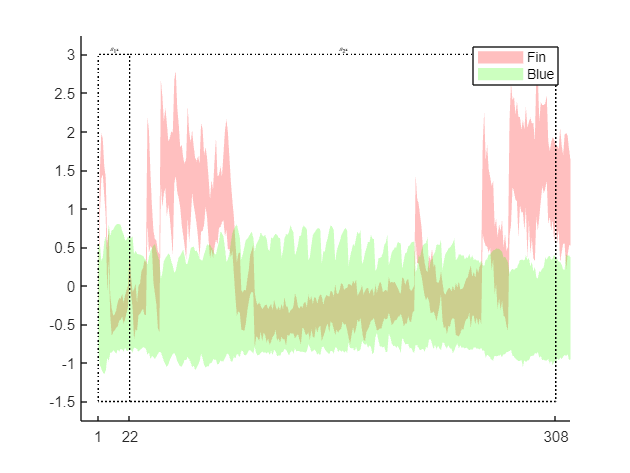

for i = 1:numel(kstart)
    fill([kstart(i), kstart(i), kend(i), kend(i)], [minx, maxx, maxx, minx], "black", ...
        "FaceColor","none", LineStyle=":")
    text(kstart(i) + (kend(i) - kstart(i))/2, 3, sprintf("$\\mathcal{S}_%d x$", i), ...
        "HorizontalAlignment","center", "VerticalAlignment","bottom", "FontSize",12, "Interpreter","latex")
end
hold off
legend(classes, "Interpreter","none")
ylim([-1.75, 3.25])
xticks([kstart, kend(end)])
xlim([-10, kend(end) + 10])

%use the detector's output annotate and distinguish from noise
r = 0.5;
rles = arrayfun(@(d) getDetRLE(d, r), segmmconv, UniformOutput=false);
idx = 1:numel(rles);
rlews = arrayfun(@(i) getDetScatCoeff(annsconv{i}, rles{i}, infoconv(i), folder, i, fsscat, fsspec, -100, 192), idx, UniformOutput=false);%size(fb.filterBanks(1).psi, 1)

idx = 100

idx = 200

idx = 300

idx = 400

idx = 500

idx = 600

idx = 700

idx = 800

idx = 900

idx = 1000

idx = 1100

idx = 1200

idx = 1300

idx = 1400

idx = 1500

idx = 1600

idx = 1700

idx = 1800

idx = 1900

idx = 2000

idx = 2100

idx = 2200

idx = 2300

idx = 2400

idx = 2500

rlewsall = vertcat(rlews{cellfun(@(x) size(x, 1) > 0, rlews)});
counts = groupcounts(rlewsall, "Annotation")

counts = 9×3 table
         Annotation         GroupCount    Percent 
    ____________________    __________    ________

    "Bm_Ant-A"                 2241         4.4304
    "Bm_Ant-B"                  639         1.2633
    "Bm_Ant-Z"                  173        0.34202
    "Bm_D"                      305        0.60298
    "Bp_20Hz"                     4       0.007908
    "Bp_20Plus"                  30        0.05931
    "Multiple"                  106        0.20956
    "Noise"                   46885         92.691
    "Unidentified_calls"        199        0.39342



rlewsall = rlewsall(rlewsall.Annotation ~= "Multiple" & rlewsall.Annotation ~= "Uncertain", :); %do not consider overlapping annotations

y = rlewsall{:, "Annotation"};
annotations = unique(y);
classes = annotations(1:7)

classes = 7×1 string array
    "Bm_Ant-A"
    "Bm_Ant-B"
    "Bm_Ant-Z"
    "Bm_D"
    "Bp_20Hz"
    "Bp_20Plus"
    "Noise"


% y(contains(y, "Bm")) = "Blue";
y(contains(y, "Bp")) = "Noise";
% y(contains(y, "Bm")) = "Signal";
% other = ~(y == "Blue" | y == "Fin");
% other = ~(y == "Signal");
% other = ~any(y == classes', 2);
other = ~contains(y, "Bm") & ~contains(y, "Bp");
y(other) = "Noise";
classes = unique(y)

classes = 5×1 string array
    "Bm_Ant-A"
    "Bm_Ant-B"
    "Bm_Ant-Z"
    "Bm_D"
    "Noise"


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.27823 |     0.36989 |     0.27823 |     0.27823 |   9.3142e-05 |      0.91661 |
|    2 | Accept |     0.47239 |     0.38123 |     0.27823 |     0.28867 |       866.19 |      0.24499 |
|    3 | Accept |     0.47239 |      0.3739 |     0.27823 |     0.27825 |       4.3001 |      0.75153 |
|    4 | Best   |      0.2566 |      0.3402 |      0.2566 |     0.25667 |   0.00015199 |       0.2747 |
|    5 | Best   |     0.25642 |     0.35671 |     0.25642 |     0.25644 |    0.0011601 |    0.0084801 |
|    6 | Best   |     0.25519 |     0.34823 |     0.25519 |     

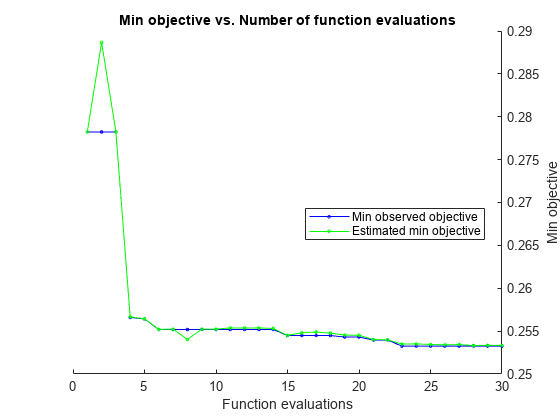

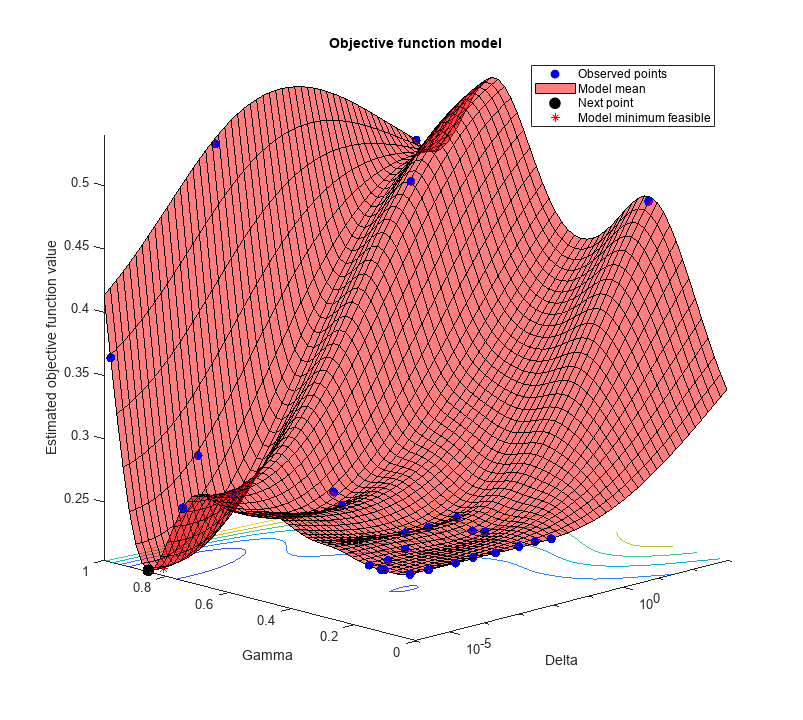


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 25.1865 seconds
Total objective function evaluation time: 10.5129

Best observed feasible point:
      Delta        Gamma 
    __________    _______

    1.1245e-06    0.10517

Observed objective function value = 0.25325
Estimated objective function value = 0.25333
Function evaluation time = 0.34569

Best estimated feasible point (according to models):
      Delta        Gamma 
    __________    _______

    1.0305e-06    0.10892

Estimated objective function value = 0.25333
Estimated function evaluation time = 0.32519




X = rlewsall{:, "WS"};



% classes = ["Fin", "Blue"];
X = double(vertcat(X{:}));
% X = X(:, [6:9, 73:97, end]);
X = X(:, 1:end-1);
% X = X(:, [1:13,26:130, 258:289,318:503,766:806,end-1,end]);
ynoiseidx = find(y == "Noise");
ysigidx = find(y ~= "Noise");
idxnoise = splitlabels(y(ynoiseidx), 3000, "randomized");
idxsignal = splitlabels(y(ysigidx), 0.8, "randomized");
idxs{1} = [ynoiseidx(idxnoise{1}); ysigidx(idxsignal{1})];
idxs{2} = [ynoiseidx(idxnoise{2}); ysigidx(idxsignal{2})];
Xn = double(X);
eps = 1e-12;
Xn(Xn < eps) = eps;
% Xn = log(Xn);
% std(Xn, 1)
Xn = ((Xn-mean(Xn, 1))./std(Xn, 1));
% Xn = double(X);
Xtrain = Xn(idxs{1}, :);
ytrain = y(idxs{1}, :);
Xtest = Xn(idxs{2}, :);
ytest = y(idxs{2}, :);

% k = 100;
% [U, S, V] = svd(Xtrain(ytrain ~= "Noise", :), "econ");
% Vk = V(:, 1:k);
% Xtrain = Xtrain * Vk ./ diag(S(1:k, 1:k))';
% Xtest =  Xtest  * Vk ./ diag(S(1:k, 1:k))';

% cls = fitcnb(Xtrain, ytrain);
cls = fitcdiscr(Xtrain, ytrain, OptimizeHyperparameters="auto", DiscrimType="pseudolinear", Gamma=0);

% cls = fitcecoc(Xtrain, ytrain);
% cls = fitcensemble(Xtrain, ytrain);
% cls = fitcsvm(Xtrain, ytrain, "PolynomialOrder",2, "KernelFunction","polynomial");
ypred = cls.predict(Xtest);
[c, order] = confusionmat(ytest, ypred)

c =        40309        1171        2509          52          77
          34          23           4           0           0
         118           2         300          22           6
          26           1          59          25          17
          12           0           4           4          15


order = 5×1 string array
    "Noise"
    "Bm_D"
    "Bm_Ant-A"
    "Bm_Ant-B"
    "Bm_Ant-Z"


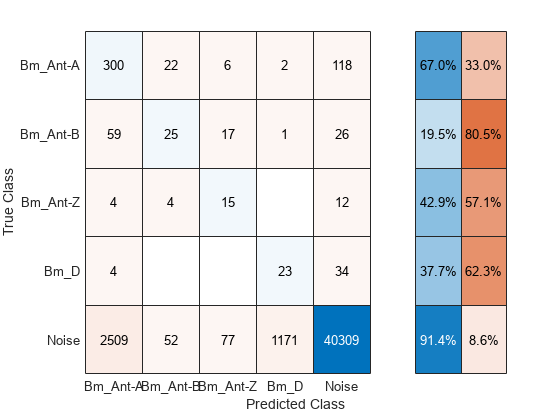

figure
confusionchart(c, order, "RowSummary","row-normalized")

c = [c(1, 1), sum(c(1, 2:end)); sum(c(2:end, 1)), sum(c(2:end, 2:end), 'all')]

c =        40309        3809
         190         482


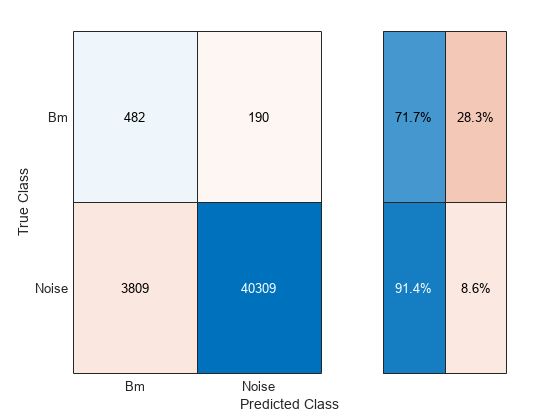

order = ["Noise", "Bm"];
figure
confusionchart(c, order, "RowSummary","row-normalized")

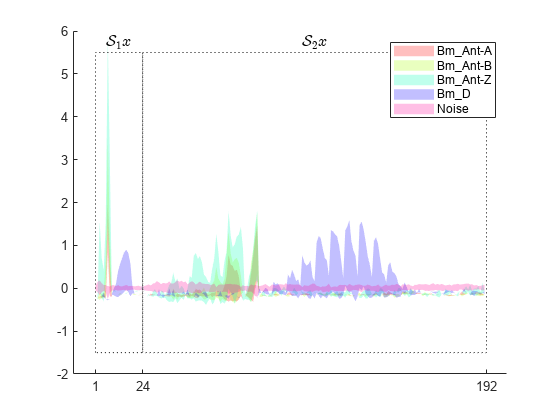


colors = ones(numel(classes), 3);
colors(:, 1) = linspace(0, 0.9, numel(classes));
colors = hsv2rgb(colors);
B = arrayfun(@(f) size(f.Psi, 1), fb.filterBanks);
for i = 1:numel(B)
    klen(i) = prod(B(1:i));    
end
kend = cumsum(klen);
kstart = [1, kend(1:end-1)];
figure
hold on
for i = 1:numel(classes)
    c = classes(i);
    col = colors(i, :);    
    mu = mean(Xtrain(ytrain == c, 1:end-1), 1);
    sigma = mad(Xtrain(ytrain == c, 1:end-1), 1);
    f = 1:size(Xtrain, 2) - 1;
    fill([f, fliplr(f)], [mu + sigma, fliplr(mu-sigma)], col, "FaceAlpha", 0.25, "LineStyle","none")    
end

minx = -1.5;
maxx = 5.5;
for i = 1:2
    fill([kstart(i), kstart(i), kend(i), kend(i)], [minx, maxx, maxx, minx], "black", ...
        "FaceColor","none", LineStyle=":")
    text(kstart(i) + (kend(i) - kstart(i))/2, maxx, sprintf("$\\mathcal{S}_%d x$", i), ...
        "HorizontalAlignment","center", "VerticalAlignment","bottom", "FontSize",12, "Interpreter","latex")
end
hold off
legend(classes, "Interpreter","none")
ylim([-2, 6])
xticks([kstart, kend(end)])
xlim([-10, kend(end) + 10])

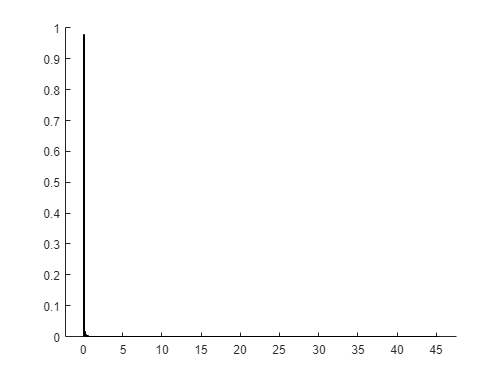


Xr = aenc.predict(Xtest);
xmse = mean((Xr - Xtest).^2, 1);
figure
hold on
histogram(xmse, 500, "Normalization","probability");

Xr = aenc.predict(Xsig);
xmse = mean((Xr - Xsig).^2, 1);
histogram(xmse, 20, "Normalization","probability");
hold off

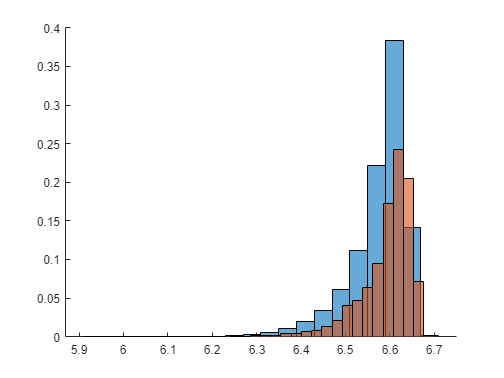

X = rlewsall{:, "WS"};
X = double(vertcat(X{:}));
y = rlewsall{:, "Annotation"};
Xn = X./median(X(y == "Noise", :), 1);
Xnoise = Xn(y == "Noise", :);
Xsig = Xn(y ~= "Noise", :);

XnoiseH = entropyWS(Xnoise);
XsigH = entropyWS(Xsig);
figure
hold on
histogram(XnoiseH, 20, "Normalization","probability")
histogram(XsigH, 20, "Normalization","probability")
hold off

function T = getDetRLE(det, r)
    if r > 1
        labels = det.probs > r*min(det.probs);
    else
        labels = det.probs > r;
    end
    T = Tools.rle(labels);
    T.Prob = arrayfun(@(i) max(det.probs(T.Start(i):T.End(i))), 1:size(T, 1))';
end

function detrle = getDetScatCoeff(ann, detrle, info, path, idx, fsscat, fsspec, anrdb, endfb1)
    d = fsspec/fsscat;
    if mod(idx, 100) == 0
        idx
    end
    fname = info.name;
    s = double(load(path + "\\scattering\\" + fname).s);
    ann = ann(ann.AnnotationToNoiseRatioDB > anrdb, :);
%     mu = median(s, 2);
    p = mean(median(s(1:endfb1, :), 2), "all");
%     s = s - mu;
    s = s./p;
    madfb1 = median(s(1:endfb1, :), 2);
    s(1:endfb1, :) = s(1:endfb1, :)./madfb1 - 1;
%     s = s - median(s, 2);
    for i = 1:size(detrle, 1)
        rle = detrle(i, :);
        ovr = rle.Start <= ann.SpectrogramEndIndex & ann.SpectrogramStartIndex <= rle.End;
        ss = rle.Start;
        se = rle.End;
        sidx = max(floor((ss-1)/d)+1, 1);
        eidx = min(ceil((se-1)/d)+1, size(s, 2));  
%         coeffs = max(s(:, sidx:eidx), [],  2)';
        coeffs = mean(s(:, sidx:eidx),  2)';
%         vars = var(s(:, sidx:eidx),1, 2)';
%         coeffs = coeffs.^2;
%         coeffs = coeffs/sum(coeffs, "all");
        detrle.WS(i) = {[coeffs, se-ss]};
        if sum(ovr) == 1
            if ann.AnnotationToNoiseRatioDB(ovr) > anrdb
            detrle.Annotation(i) = ann.Annotation(ovr);
            else
              detrle.Annotation(i) = "Uncertain";
            end
        elseif sum(ovr) > 1
            detrle.Annotation(i) = "Multiple";
        else
            detrle.Annotation(i) = "Noise";
        end
    end

end

function o = detoverlaps(rle, ann)
    o = rle.Start <= ann.SpectrogramEndIndex & ann.SpectrogramStartIndex <= rle.End;
end

function ann = getScatCoeff(ann, info, path, idx, fsscat, fsspec)
d = fsspec/fsscat;
if mod(idx, 100) == 0
    idx
end
    fname = info.name;
    s = load(path + "\\scattering\\" + fname).s;
    mu = median(s, 2);
%     s = max(s - mu, 0);
% %     stdev = 1.141*median(abs(s - mu), 2);
% %     s = (s)./stdev;
    for i = 1:size(ann, 1)
        a = ann(i, :);
        ss = a.SpectrogramStartIndex ;
        se = a.SpectrogramEndIndex;

        sidx = max(floor((ss-1)/d)+1, 1);
        eidx = min(ceil((se-1)/d)+1, size(s, 2));  
%         coeffs = max(s(:, sidx:eidx), [],  2)';
        coeffs = mean(s(:, sidx:eidx),  2)';
%         coeffs = coeffs.^2;
%         coeffs = coeffs/sum(coeffs, "all");
        ann.WS(i) = {[coeffs, se-ss]};
    end
end

function H = entropyWS(X)
    s = sum(X, 2);
    Xn = X./s;
    H = -sum(Xn.*log(Xn), 2);
end